## Morphology (形態學)

### Dilation (膨脹)

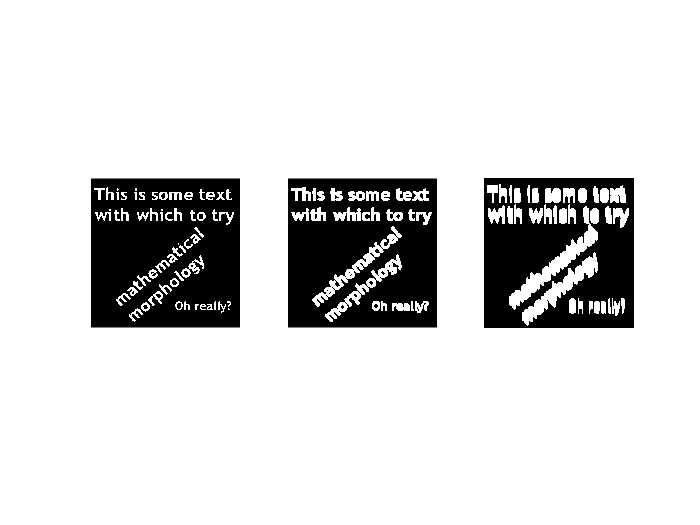

img = imread("Image\morph_text.png");
SE1 = ones(3, 3); % 以 3x3 的方陣進行膨脹
SE2 = strel("rectangle", [15, 1]); % 以 15x1 的長方形進行膨脹
imgn1 = imdilate(img, SE1);
imgn2 = imdilate(img, SE2);
figure;
subplot(131); imshow(img);
subplot(132); imshow(imgn1);
subplot(133); imshow(imgn2);

## Erosion (侵蝕)

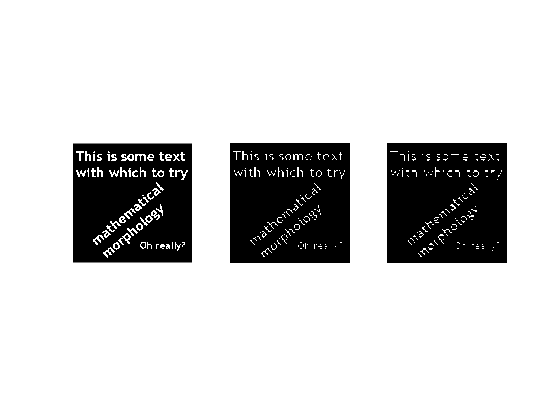

SE1 = ones(3, 3); % 以 3x3 的方陣進行侵蝕
SE2 = strel("rectangle", [1, 5]); % 以 1x5 的長方形進行侵蝕
imgn1 = imerode(img, SE1);
imgn2 = imerode(img, SE2);
figure;
subplot(131); imshow(img);
subplot(132); imshow(imgn1);
subplot(133); imshow(imgn2);

### 運用 Erosion 尋找內部邊界

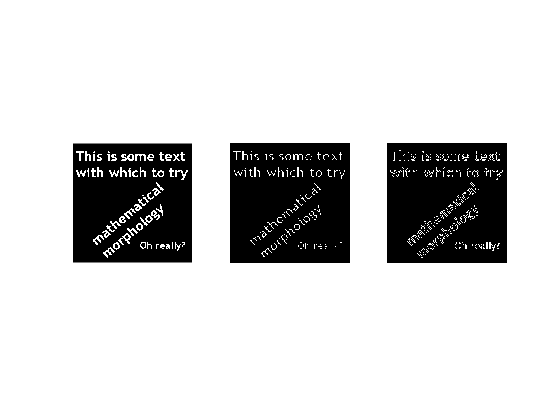

SE1 = ones(3, 3); % 以 3x3 的方陣進行侵蝕
imgn1 = imerode(img, SE1);
imgn2 = img - imgn1;
figure; 
subplot(131); imshow(img);
subplot(132); imshow(imgn1);
subplot(133); imshow(imgn2);

### 運用 Dilation 尋找外部邊界

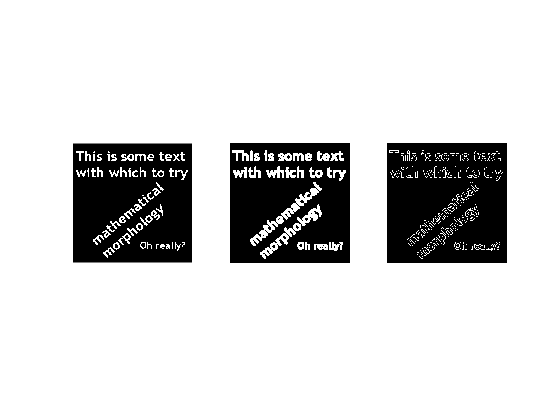

SE1 = ones(3, 3); % 以 3x3 的方陣進行膨脹
imgn1 = imdilate(img, SE1);
imgn2 = imgn1 - img;
figure; 
subplot(131); imshow(img);
subplot(132); imshow(imgn1);
subplot(133); imshow(imgn2);

### Opening (開啟)

即是先做 erosion 再做 dilation，可以用來過濾噪點或把小的突出、連接平滑化

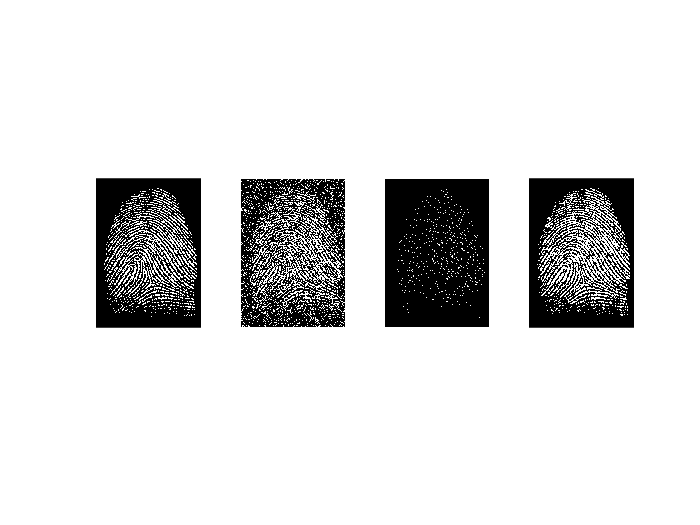

img = rgb2gray(imread("Image\fingerprint.jpg"));
T = graythresh(img);
b = imbinarize(img, T);
b = (b == 0);
imgb = mat2gray(b);
img_noise = imnoise(imgb, "salt & pepper", 0.3);
SE = ones(3, 3);
imge = imerode(img_noise, SE);
imgd = imdilate(imdilate(imdilate(imge, SE), SE), SE);
figure;
subplot(141); imshow(imgb);
subplot(142); imshow(img_noise);
subplot(143); imshow(imge);
subplot(144); imshow(imgd);

由左到右分別為原圖、撒上噪點的圖、erode 完的圖、dilate 完的圖。可以看到在 erosion 的時候可以消掉 noise，但這會使得圖一起被 erode，這個時候再做 dilate 便可以將圖變回原來的樣貌。

### Closing (關閉)

即是先做 dilation 再做 erosion，可以用來把小洞補起來同時維持比較大的 object 的形狀

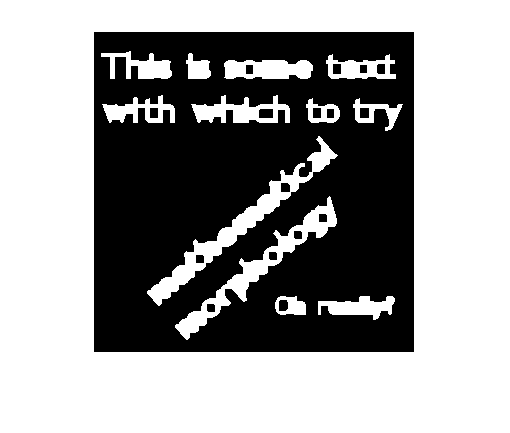

img = imread("Image\morph_text.png");
SE = ones(4, 4);
imgd = imdilate(imdilate(img, SE), SE);
imge = imerode(imerode(imgd, SE), SE);
figure; imshow(imge);

### 灰階形態學

前面僅將 morphology 定義在 binary image 上，但在 grayscale image 上也可以使用 morphology。 erosion 跟 dilation 的定義分別為

假設灰階影像為

                        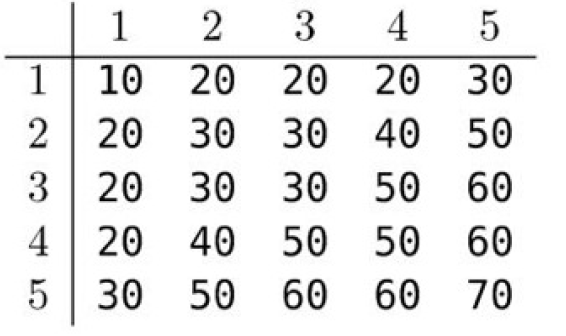

而 structual element 為

                                        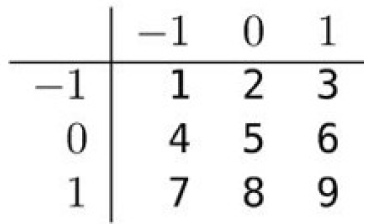

則 erosion 的結果為

                                            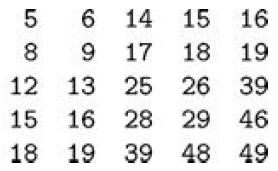

dilation 的結果為